Scatter plot of feeder preference index (FPI) vs reward preference index (RPI)

A = struct([]);
bname_full = {'14447' '11827' '29924' '14406' '14561' '14633' '14662' '14531' '71050' '9776'};

## Social, multi-flavor

### 200210_1

rootdir = 'Z:\users\Tatsumi\data\MultiReward\multibat\240210_1';

cd(rootdir)
load(fullfile(rootdir,'analysis','exp_info.mat'),'mtData')
[BhvData, AnalogData] = PreprocessBhvData(rootdir);

Extracted data are found in the directory.
Behavior data are found in the directory.
Analog signal data are found.


RewardData = PreprocessRewardData(rootdir);

Final MinPeakDistance was 1.0 
224 peaks were detected. 
2 artifacts were detected. It matches with the number of sessions. 
All rewarding landings were recorded and detected.


Landings_fd = extractLandings(BhvData,RewardData,mtData,'include','feeder');

bnames = mtData.bname;
n_tags = length(bnames);
for bb = 1:n_tags
    % Compute SPI
    num_oth_on_feeder = Landings_fd(bb).num_oth_on_feeder;
    landed_fd = Landings_fd(bb).closest_feeder(:,2);
    nonlanded_fd = -1 * landed_fd + 3; % switch the values
    num_oth_same_fd = zeros(length(landed_fd),1);
    num_oth_diff_fd = zeros(length(nonlanded_fd),1);
    for ll = 1:length(landed_fd)
        if landed_fd(ll) == 1 || landed_fd(ll) == 2
            num_oth_same_fd(ll) = num_oth_on_feeder(ll,landed_fd(ll));
            num_oth_diff_fd(ll) = num_oth_on_feeder(ll,nonlanded_fd(ll));
        end
    end
    S1 = sum(num_oth_same_fd);
    S2 = sum(num_oth_diff_fd);
    
    i = length(A);
    A(i+1).bname  = bnames{bb};
    A(i+1).bid = num2str(find(strcmp(bnames{bb},bname_full)));
    A(i+1).FPI    = mean(Landings_fd(bb).FPI,'omitnan'); % feeder preference index;
    A(i+1).RPI    = mean(Landings_fd(bb).RPI,'omitnan');
    A(i+1).SPI    = (S1 - S2) / (S1 + S2); % social preference index
    A(i+1).exptype    = 'social';    
    A(i+1).date = mtData.rec_date;
end

### 200210_2

rootdir = 'Z:\users\Tatsumi\data\MultiReward\multibat\240210_2';

cd(rootdir)
load(fullfile(rootdir,'analysis','exp_info.mat'),'mtData')
[BhvData, AnalogData] = PreprocessBhvData(rootdir);

Extracted data are found in the directory.
Behavior data are found in the directory.
Analog signal data are found.


RewardData = PreprocessRewardData(rootdir);

Final MinPeakDistance was 0.5 
212 peaks were detected. 
1 artifacts were detected. It matches with the number of sessions. 
All rewarding landings were recorded and detected.


Landings_fd = extractLandings(BhvData,RewardData,mtData,'include','feeder');

bnames = mtData.bname;
n_tags = length(bnames);
for bb = 1:n_tags
    % Compute SPI
    num_oth_on_feeder = Landings_fd(bb).num_oth_on_feeder;
    landed_fd = Landings_fd(bb).closest_feeder(:,2);
    nonlanded_fd = -1 * landed_fd + 3; % switch the values
    num_oth_same_fd = zeros(length(landed_fd),1);
    num_oth_diff_fd = zeros(length(nonlanded_fd),1);
    for ll = 1:length(landed_fd)
        if landed_fd(ll) == 1 || landed_fd(ll) == 2
            num_oth_same_fd(ll) = num_oth_on_feeder(ll,landed_fd(ll));
            num_oth_diff_fd(ll) = num_oth_on_feeder(ll,nonlanded_fd(ll));
        end
    end
    S1 = sum(num_oth_same_fd);
    S2 = sum(num_oth_diff_fd);
    
    i = length(A);
    A(i+1).bname  = bnames{bb};
    A(i+1).bid = num2str(find(strcmp(bnames{bb},bname_full)));
    A(i+1).FPI    = mean(Landings_fd(bb).FPI,'omitnan'); % feeder preference index;
    A(i+1).RPI    = mean(Landings_fd(bb).RPI,'omitnan');
    A(i+1).SPI    = (S1 - S2) / (S1 + S2); % social preference index
    A(i+1).exptype    = 'social';    
    A(i+1).date = mtData.rec_date;
end

### 200211_2

rootdir = 'Z:\users\Tatsumi\data\MultiReward\multibat\240211_2';

cd(rootdir)
load(fullfile(rootdir,'analysis','exp_info.mat'),'mtData')
[BhvData, AnalogData] = PreprocessBhvData(rootdir);

Extracted data are found in the directory.
Behavior data are found in the directory.
Analog signal data are found.


RewardData = PreprocessRewardData(rootdir);

Final MinPeakDistance was 0.4 
195 peaks were detected. 
2 artifacts were detected. It matches with the number of sessions. 
All rewarding landings were recorded and detected.


Landings_fd = extractLandings(BhvData,RewardData,mtData,'include','feeder');

bnames = mtData.bname;
n_tags = length(bnames);
for bb = 1:n_tags
    % Compute SPI
    num_oth_on_feeder = Landings_fd(bb).num_oth_on_feeder;
    landed_fd = Landings_fd(bb).closest_feeder(:,2);
    nonlanded_fd = -1 * landed_fd + 3; % switch the values
    num_oth_same_fd = zeros(length(landed_fd),1);
    num_oth_diff_fd = zeros(length(nonlanded_fd),1);
    for ll = 1:length(landed_fd)
        if landed_fd(ll) == 1 || landed_fd(ll) == 2
            num_oth_same_fd(ll) = num_oth_on_feeder(ll,landed_fd(ll));
            num_oth_diff_fd(ll) = num_oth_on_feeder(ll,nonlanded_fd(ll));
        end
    end
    S1 = sum(num_oth_same_fd);
    S2 = sum(num_oth_diff_fd);
    
    i = length(A);
    A(i+1).bname  = bnames{bb};
     A(i+1).bid = num2str(find(strcmp(bnames{bb},bname_full)));
    A(i+1).bid = num2str(find(strcmp(bnames{bb},bname_full)));
    A(i+1).FPI    = mean(Landings_fd(bb).FPI,'omitnan'); % feeder preference index;
    A(i+1).RPI    = mean(Landings_fd(bb).RPI,'omitnan');
    A(i+1).SPI    = (S1 - S2) / (S1 + S2); % social preference index
    A(i+1).exptype    = 'social';    
    A(i+1).date = mtData.rec_date;
end

### 200212

rootdir = 'Z:\users\Tatsumi\data\MultiReward\multibat\240212';

cd(rootdir)
load(fullfile(rootdir,'analysis','exp_info.mat'),'mtData')
[BhvData, AnalogData] = PreprocessBhvData(rootdir);

Extracted data are found in the directory.
Behavior data are found in the directory.
Analog signal data are found.


RewardData = PreprocessRewardData(rootdir);

Final MinPeakDistance was 0.6 
120 peaks were detected. 
1 artifacts were detected. It matches with the number of sessions. 
All rewarding landings were recorded and detected.


Landings_fd = extractLandings(BhvData,RewardData,mtData,'include','feeder');

bnames = mtData.bname;
n_tags = length(bnames);
for bb = 1:n_tags
    % Compute SPI
    num_oth_on_feeder = Landings_fd(bb).num_oth_on_feeder;
    landed_fd = Landings_fd(bb).closest_feeder(:,2);
    nonlanded_fd = -1 * landed_fd + 3; % switch the values
    num_oth_same_fd = zeros(length(landed_fd),1);
    num_oth_diff_fd = zeros(length(nonlanded_fd),1);
    for ll = 1:length(landed_fd)
        if landed_fd(ll) == 1 || landed_fd(ll) == 2
            num_oth_same_fd(ll) = num_oth_on_feeder(ll,landed_fd(ll));
            num_oth_diff_fd(ll) = num_oth_on_feeder(ll,nonlanded_fd(ll));
        end
    end
    S1 = sum(num_oth_same_fd);
    S2 = sum(num_oth_diff_fd);
    
    i = length(A);
    A(i+1).bname  = bnames{bb};
     A(i+1).bid = num2str(find(strcmp(bnames{bb},bname_full)));
    A(i+1).FPI    = mean(Landings_fd(bb).FPI,'omitnan'); % feeder preference index;
    A(i+1).RPI    = mean(Landings_fd(bb).RPI,'omitnan');
    A(i+1).SPI    = (S1 - S2) / (S1 + S2); % social preference index
    A(i+1).exptype    = 'social';    
    A(i+1).date = mtData.rec_date;
end

### Single bat

### 14662, day 240209

rootdir = 'Z:\users\Tatsumi\data\MultiReward\singlebat\14662\240209';

cd(rootdir)
load(fullfile(rootdir,'analysis','exp_info.mat'),'mtData')
[BhvData, AnalogData] = PreprocessBhvData(rootdir);

Extracted data are found in the directory.
Behavior data are found in the directory.
Analog signal data are found.


RewardData = PreprocessRewardData(rootdir);

Final MinPeakDistance was 1.0 
25 peaks were detected. 
1 artifacts were detected. It matches with the number of sessions. 
All rewarding landings were recorded and detected.


Landings_fd = extractLandings(BhvData,RewardData,mtData,'include','feeder');

bnames = mtData.bname;
n_tags = length(bnames);
for bb = 1:n_tags
    i = length(A);
    A(i+1).bname  = bnames{bb};
     A(i+1).bid = num2str(find(strcmp(bnames{bb},bname_full)));
    A(i+1).FPI    = mean(Landings_fd(bb).FPI,'omitnan'); % feeder preference index;
    A(i+1).RPI    = mean(Landings_fd(bb).RPI,'omitnan');
    A(i+1).SPI    = nan; % social preference index
    A(i+1).exptype    = 'single';    
    A(i+1).date = mtData.rec_date;
end

### 14662, day 240210

rootdir = 'Z:\users\Tatsumi\data\MultiReward\singlebat\14662\240210';

cd(rootdir)
load(fullfile(rootdir,'analysis','exp_info.mat'),'mtData')
[BhvData, AnalogData] = PreprocessBhvData(rootdir);

Extracted data are found in the directory.
Behavior data are found in the directory.
Analog signal data are found.


RewardData = PreprocessRewardData(rootdir);

Final MinPeakDistance was 1.0 
12 peaks were detected. 
1 artifacts were detected. It matches with the number of sessions. 
All rewarding landings were recorded and detected.


Landings_fd = extractLandings(BhvData,RewardData,mtData,'include','feeder');

bnames = mtData.bname;
n_tags = length(bnames);
for bb = 1:n_tags
    i = length(A);
    A(i+1).bname  = bnames{bb};
     A(i+1).bid = num2str(find(strcmp(bnames{bb},bname_full)));
    A(i+1).FPI    = mean(Landings_fd(bb).FPI,'omitnan'); % feeder preference index;
    A(i+1).RPI    = mean(Landings_fd(bb).RPI,'omitnan');
    A(i+1).SPI    = nan; % social preference index
    A(i+1).exptype    = 'single';    
    A(i+1).date = mtData.rec_date;
end

### 14662, day 240211

rootdir = 'Z:\users\Tatsumi\data\MultiReward\singlebat\14662\240211';

cd(rootdir)
load(fullfile(rootdir,'analysis','exp_info.mat'),'mtData')
[BhvData, AnalogData] = PreprocessBhvData(rootdir);

Extracted data are found in the directory.
Behavior data are found in the directory.
Analog signal data are found.


RewardData = PreprocessRewardData(rootdir);

Final MinPeakDistance was 1.0 
28 peaks were detected. 
2 artifacts were detected. It matches with the number of sessions. 
All rewarding landings were recorded and detected.


Landings_fd = extractLandings(BhvData,RewardData,mtData,'include','feeder');

bnames = mtData.bname;
n_tags = length(bnames);
for bb = 1:n_tags
    i = length(A);
    A(i+1).bname  = bnames{bb};
     A(i+1).bid = num2str(find(strcmp(bnames{bb},bname_full)));
    A(i+1).FPI    = mean(Landings_fd(bb).FPI,'omitnan'); % feeder preference index;
    A(i+1).RPI    = mean(Landings_fd(bb).RPI,'omitnan');
    A(i+1).SPI    = nan; % social preference index
    A(i+1).exptype    = 'single';    
    A(i+1).date = mtData.rec_date;
end

### 14633, day 240208

rootdir = 'Z:\users\Tatsumi\data\MultiReward\singlebat\14633\240208';

cd(rootdir)
load(fullfile(rootdir,'analysis','exp_info.mat'),'mtData')
[BhvData, AnalogData] = PreprocessBhvData(rootdir);

Extracted data are found in the directory.
Behavior data are found in the directory.
Analog signal data are found.


RewardData = PreprocessRewardData(rootdir);

Final MinPeakDistance was 1.0 
26 peaks were detected. 
1 artifacts were detected. It matches with the number of sessions. 
All rewarding landings were recorded and detected.


Landings_fd = extractLandings(BhvData,RewardData,mtData,'include','feeder');

bnames = mtData.bname;
n_tags = length(bnames);
for bb = 1:n_tags
    i = length(A);
    A(i+1).bname  = bnames{bb};
     A(i+1).bid = num2str(find(strcmp(bnames{bb},bname_full)));
    A(i+1).FPI    = mean(Landings_fd(bb).FPI,'omitnan'); % feeder preference index;
    A(i+1).RPI    = mean(Landings_fd(bb).RPI,'omitnan');
    A(i+1).SPI    = nan; % social preference index
    A(i+1).exptype    = 'single';    
    A(i+1).date = mtData.rec_date;
end

### 14531, day 240207

rootdir = 'Z:\users\Tatsumi\data\MultiReward\singlebat\14531\240207';

cd(rootdir)
load(fullfile(rootdir,'analysis','exp_info.mat'),'mtData')
[BhvData, AnalogData] = PreprocessBhvData(rootdir);

Extracted data are found in the directory.
Behavior data are found in the directory.
Analog signal data are found.


RewardData = PreprocessRewardData(rootdir);

Final MinPeakDistance was 1.0 
23 peaks were detected. 
1 artifacts were detected. It matches with the number of sessions. 
All rewarding landings were recorded and detected.


Landings_fd = extractLandings(BhvData,RewardData,mtData,'include','feeder');

bnames = mtData.bname;
n_tags = length(bnames);
for bb = 1:n_tags
    i = length(A);
    A(i+1).bname  = bnames{bb};
     A(i+1).bid = num2str(find(strcmp(bnames{bb},bname_full)));
    A(i+1).FPI    = mean(Landings_fd(bb).FPI,'omitnan'); % feeder preference index;
    A(i+1).RPI    = mean(Landings_fd(bb).RPI,'omitnan');
    A(i+1).SPI    = nan; % social preference index
    A(i+1).exptype    = 'single';    
    A(i+1).date = mtData.rec_date;
end


### Plot



% Bar plot
x = 1:10;
y = zeros(1,10); % count

for bb = 1:n_tags
    idx = strcmp({B.bid},{sprintf('%s',bb)}) 

B = A;

% sort
txt_str = {B.bid};
[~,sort_idx] = sort(txt_str);
B = B(sort_idx);

% extract only the bat id
% for j = 1:length(B)
%     B(j).bname = B(j).bname(3:end);
% end


% Color data
clr_mat = jet;
xq = linspace(1,size(clr_mat,1),10);
new_clr_mat = zeros(10,3);
for clr = 1:3
    new_clr_mat(:,clr) = interp1(1:size(clr_mat,1),clr_mat(:,clr),xq);
end
clr_vector = zeros(length(B),3);
for j = 1:length(B)
    clr_vector(j,:) = new_clr_mat(str2double(B(j).bid),:);
end




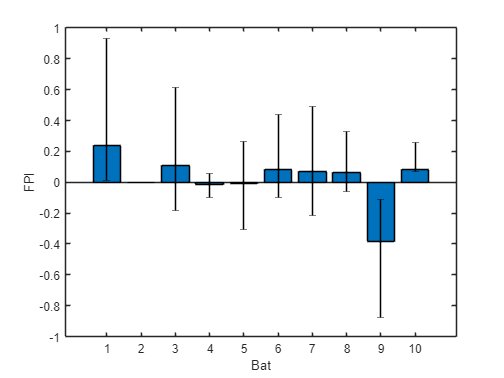

% Bar plot
% FPI
x = [B.FPI];

labels = 1:10;
cnt = zeros(1,10);
x_high = zeros(1,10);
x_low = zeros(1,10);


for bb = 1:10
    idx = strcmp({B.bid},{sprintf('%d',bb)});
    cnt(bb) = mean(x(idx),'omitnan');
    x_high(bb) = cnt(bb) + std(x(idx),'omitnan');
    x_low(bb) = cnt(bb) - std(x(idx),'omitnan');
end


fig = figure;
set(gca,'FontSize',20)
bar(labels,cnt)
hold on 
er = errorbar(labels,cnt, x_low, x_high);    
er.Color = [0 0 0];                            
er.LineStyle = 'none';  
hold off
xlabel('Bat')
ylabel('FPI')
saveas(fig,fullfile('Z:\users\Tatsumi\data\MultiReward\Analysis','figure','FPI_bar.jpg'))

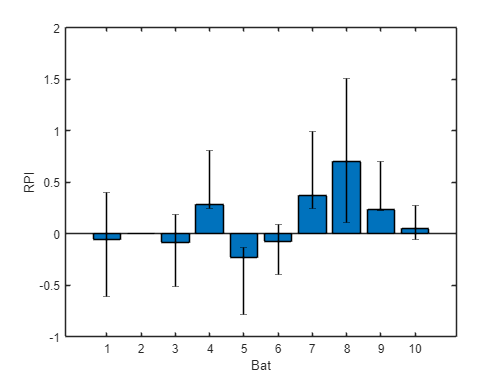


% Bar plot
% RPI
x = [B.RPI];

labels = 1:10;
cnt = zeros(1,10);
x_high = zeros(1,10);
x_low = zeros(1,10);


for bb = 1:10
    idx = strcmp({B.bid},{sprintf('%d',bb)});
    cnt(bb) = mean(x(idx),'omitnan');
    x_high(bb) = cnt(bb) + std(x(idx),'omitnan');
    x_low(bb) = cnt(bb) - std(x(idx),'omitnan');
end


fig = figure;
set(gca,'FontSize',20)
bar(labels,cnt)
hold on 
er = errorbar(labels,cnt, x_low, x_high);    
er.Color = [0 0 0];                            
er.LineStyle = 'none';  
hold off
xlabel('Bat')
ylabel('RPI')
saveas(fig,fullfile('Z:\users\Tatsumi\data\MultiReward\Analysis','figure','RPI_bar.jpg'))

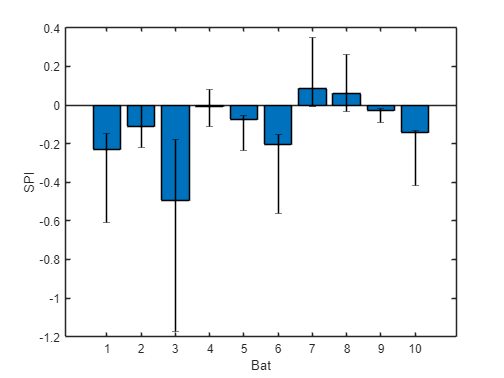


% Bar plot
% SPI
x = [B.SPI];

labels = 1:10;
cnt = zeros(1,10);
x_high = zeros(1,10);
x_low = zeros(1,10);


for bb = 1:10
    idx = strcmp({B.exptype},{'social'}) & strcmp({B.bid},{sprintf('%d',bb)});
    cnt(bb) = mean(x(idx),'omitnan');
    x_high(bb) = cnt(bb) + std(x(idx),'omitnan');
    x_low(bb) = cnt(bb) - std(x(idx),'omitnan');
end


fig = figure;
set(gca,'FontSize',20)
bar(labels,cnt)
hold on 
er = errorbar(labels,cnt, x_low, x_high);    
er.Color = [0 0 0];                            
er.LineStyle = 'none';  
hold off
xlabel('Bat')
ylabel('SPI')
saveas(fig,fullfile('Z:\users\Tatsumi\data\MultiReward\Analysis','figure','SPI_bar.jpg'))

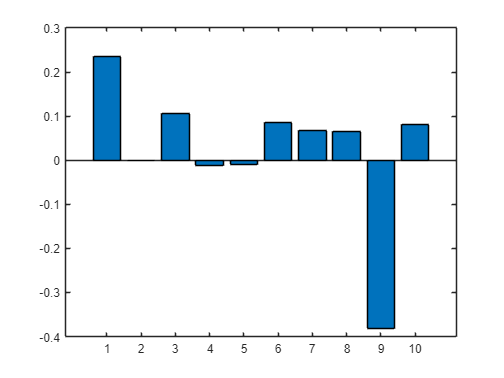


% FPI vs RPI
x = [B.FPI];
y = [B.RPI];
txt_str = {B.bid};

ylabel('')
    % x(idx),y(idx),txt_str(idx)

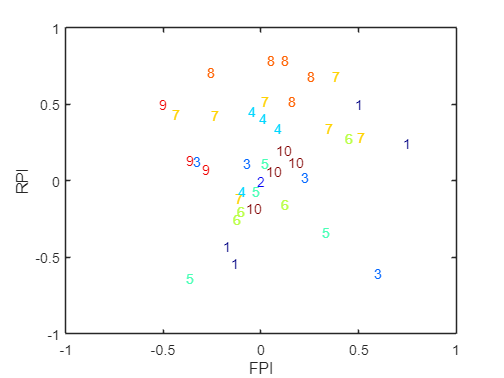



fig = figure; textscatter(x,y,txt_str,'TextDensityPercentage',100,'ColorData',clr_vector)
fontsize(fig,12,'points')

xlim([-1,1])
ylim([-1,1])
xlabel('FPI')
ylabel('RPI')
saveas(fig,fullfile('Z:\users\Tatsumi\data\MultiReward\Analysis','figure','FPI_RPI_distribution.jpg'))

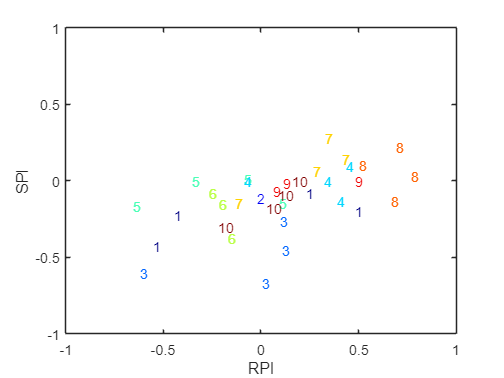


% Plot RPI vs SPI
x = [B.RPI];
y = [B.SPI];
txt_str = {B.bid};

fig = figure; textscatter(x,y,txt_str,'TextDensityPercentage',100,'ColorData',clr_vector)
fontsize(fig,12,'points') 

xlim([-1,1])
ylim([-1,1])
xlabel('RPI')
ylabel('SPI')
saveas(fig,fullfile('Z:\users\Tatsumi\data\MultiReward\Analysis','figure','RPI_SPI_distribution.jpg'))

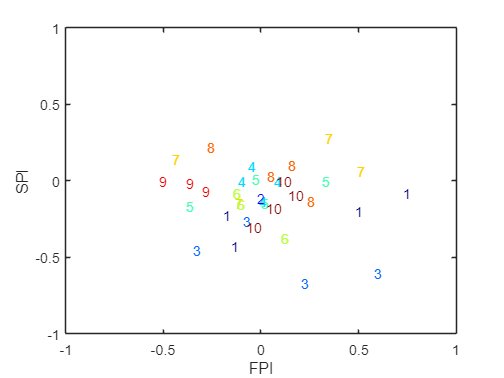


% Plot FPI vs SPI
x = [B.FPI];
y = [B.SPI];
txt_str = {B.bid};

fig = figure; textscatter(x,y,txt_str,'TextDensityPercentage',100,'ColorData',clr_vector)
fontsize(fig,12,'points')

xlim([-1,1])
ylim([-1,1])
xlabel('FPI')
ylabel('SPI')
saveas(fig,fullfile('Z:\users\Tatsumi\data\MultiReward\Analysis','figure','FPI_SPI_distribution.jpg'))

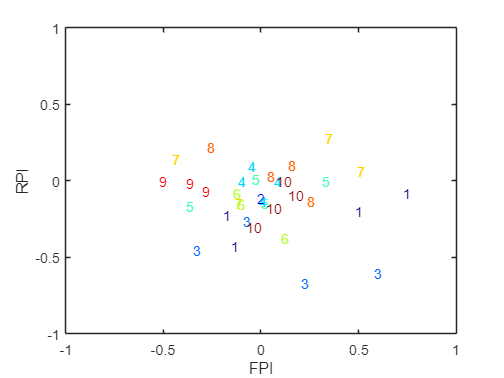




% social vs single bat
% social
idx = strcmp({B.exptype},{'social'});

fig = figure; textscatter(x(idx),y(idx),txt_str(idx),'TextDensityPercentage',100,'ColorData',clr_vector(idx,:))
fontsize(fig,12,'points')

xlim([-1,1])
ylim([-1,1])
xlabel('FPI')
ylabel('RPI')
saveas(fig,fullfile('Z:\users\Tatsumi\data\MultiReward\Analysis','figure','PI_distribution_social.jpg'))

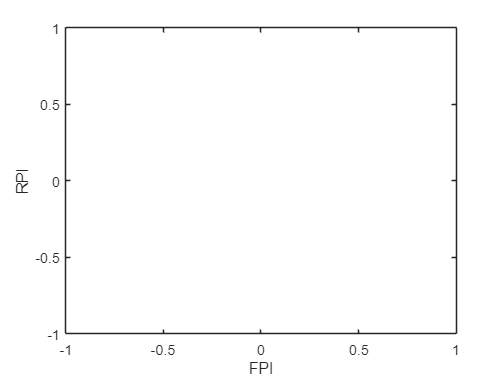


% alone
idx = strcmp({B.exptype},{'single'});

fig = figure; textscatter(x(idx),y(idx),txt_str(idx),'TextDensityPercentage',100,'ColorData',clr_vector(idx,:))
fontsize(fig,12,'points')

xlim([-1,1])
ylim([-1,1])
xlabel('FPI')
ylabel('RPI')

saveas(fig,fullfile('Z:\users\Tatsumi\data\MultiReward\Analysis','figure','PI_distribution_alone.jpg'))

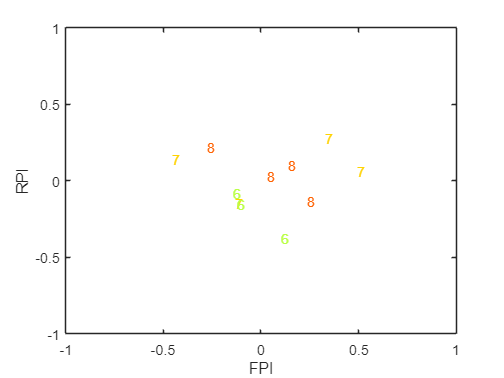



% alone
idx = strcmp({B.exptype},{'social'}) & (strcmp({B.bid},{'6'}) |  strcmp({B.bid},{'7'}) | strcmp({B.bid},{'8'}));

fig = figure; textscatter(x(idx),y(idx),txt_str(idx),'TextDensityPercentage',100,'ColorData',clr_vector(idx,:))
fontsize(fig,12,'points')

xlim([-1,1])
ylim([-1,1])
xlabel('FPI')
ylabel('RPI')
saveas(fig,fullfile('Z:\users\Tatsumi\data\MultiReward\Analysis','figure','PI_distribution_social_678.jpg'))


% alone
idx = strcmp({B.exptype},{'single'}) & (strcmp({B.bid},{'6'}) |  strcmp({B.bid},{'7'}) | strcmp({B.bid},{'8'}));
fig = figure; textscatter(x(idx),y(idx),txt_str(idx),'TextDensityPercentage',100,'ColorData',clr_vector(idx,:))
fontsize(fig,12,'points')

xlim([-1,1])
ylim([-1,1])
xlabel('FPI')
ylabel('RPI')
saveas(fig,fullfile('Z:\users\Tatsumi\data\MultiReward\Analysis','figure','PI_distribution_alone_678.jpg'))



% 
% A = struct([])
% 
% % Social multi-flavor foraging experiments
% % Day 200210_1
% i = length(A);
% A(i+1).bname  = 'bt1';
% A(i+1).FPI    = -0.13;
% A(i+1).RPI    = -0.53;
% A(i+1).date   = '200210_1';
% A(i+1).exptype    = 'social';
% 
% A(i+2).bname  = 'bt2';
% A(i+2).FPI    = nan;
% A(i+2).RPI    = nan;
% A(i+2).date   = '200210_1';
% A(i+2).exptype    = 'social';
% 
% A(i+3).bname  = 'bt3';
% A(i+3).FPI    = 0.60;
% A(i+3).RPI    = -0.6;
% A(i+3).date   = '200210_1';
% A(i+3).exptype    = 'social';
% 
% A(i+4).bname  = 'bt4';
% A(i+4).FPI    = 0.01;
% A(i+4).RPI    = 0.41;
% A(i+4).date   = '200210_1';
% A(i+4).exptype    = 'social';
% 
% A(i+5).bname  = 'bt5';
% A(i+5).FPI    = 0.02;
% A(i+5).RPI    = 0.11;
% A(i+5).date   = '200210_1';
% A(i+5).exptype    = 'social';
% 
% A(i+6).bname  = 'bt6';
% A(i+6).FPI    = 0.13;
% A(i+6).RPI    = -0.19;
% A(i+6).date   = '200210_1';
% A(i+6).exptype    = 'social';
% 
% A(i+7).bname  = 'bt7';
% A(i+7).FPI    = -0.44;
% A(i+7).RPI    = 0.44;
% A(i+7).date   = '200210_1';
% A(i+7).exptype    = 'social';
% 
% A(i+8).bname  = 'bt8';
% A(i+8).FPI    = -0.26;
% A(i+8).RPI    = 0.71;
% A(i+8).date   = '200210_1';
% A(i+8).exptype    = 'social';
% 
% A(i+9).bname  = 'bt9';
% A(i+9).FPI    = -0.50;
% A(i+9).RPI    = 0.50;
% A(i+9).date   = '200210_1';
% A(i+9).exptype    = 'social';
% 
% A(i+10).bname  = 'bt10';
% A(i+10).FPI    = 0.18;
% A(i+10).RPI    = 0.13;
% A(i+10).date   = '200210_1';
% A(i+10).exptype    = 'social';
% 

Day 200210_2

% i = length(A);
% A(i+1).bname  = 'bt1';
% A(i+1).FPI    = -0.17;
% A(i+1).RPI    = -0.42;
% A(i+1).date   = '200210_2';
% A(i+1).exptype    = 'social';
% 
% A(i+2).bname  = 'bt2';
% A(i+2).FPI    = nan;
% A(i+2).RPI    = nan;
% A(i+2).date   = '200210_2';
% A(i+2).exptype    = 'social';
% 
% A(i+3).bname  = 'bt3';
% A(i+3).FPI    = -0.33;
% A(i+3).RPI    = 0.13;
% A(i+3).date   = '200210_2';
% A(i+3).exptype    = 'social';
% 
% A(i+4).bname  = 'bt4';
% A(i+4).FPI    = -0.04;
% A(i+4).RPI    = 0.46;
% A(i+4).date   = '200210_2';
% A(i+4).exptype    = 'social';
% 
% A(i+5).bname  = 'bt5';
% A(i+5).FPI    = -0.36;
% A(i+5).RPI    = -0.64;
% A(i+5).date   = '200210_2';
% A(i+5).exptype    = 'social';
% 
% A(i+6).bname  = 'bt7';
% A(i+6).FPI    = 0.35;
% A(i+6).RPI    = 0.35;
% A(i+6).date   = '200210_2';
% A(i+6).exptype    = 'social';
% 
% A(i+7).bname  = 'bt8';
% A(i+7).FPI    = 0.16;
% A(i+7).RPI    = 0.52;
% A(i+7).date   = '200210_2';
% A(i+7).exptype    = 'social';
% 
% A(i+8).bname  = 'bt9';
% A(i+8).FPI    = -0.28;
% A(i+8).RPI    = 0.08;
% A(i+8).date   = '200210_2';
% A(i+8).exptype    = 'social';
% 
% A(i+9).bname  = 'bt10';
% A(i+9).FPI    = -0.04;
% A(i+9).RPI    = -0.18;
% A(i+9).date   = '200210_2';
% A(i+9).exptype    = 'social';
% 

Day 200211_2

% i = length(A);
% A(i+1).bname  = 'bt1';
% A(i+1).FPI    = 0.75;
% A(i+1).RPI    = 0.25;
% A(i+1).date   = '200211_2';
% A(i+1).exptype    = 'social';
% 
% A(i+2).bname  = 'bt2';
% A(i+2).FPI    = 0;
% A(i+2).RPI    = 0;
% A(i+2).date   = '200211_2';
% A(i+2).exptype    = 'social';
% 
% A(i+3).bname  = 'bt3';
% A(i+3).FPI    = -0.25;
% A(i+3).RPI    = 0.03;
% A(i+3).date   = '200211_2';
% A(i+3).exptype    = 'social';
% 
% A(i+4).bname  = 'bt4';
% A(i+4).FPI    = -0.12;
% A(i+4).RPI    = -0.08;
% A(i+4).date   = '200211_2';
% A(i+4).exptype    = 'social';
% 
% A(i+5).bname  = 'bt5';
% A(i+5).FPI    = -0.03;
% A(i+5).RPI    = -0.07;
% A(i+5).date   = '200211_2';
% A(i+5).exptype    = 'social';
% 
% A(i+6).bname  = 'bt6';
% A(i+6).FPI    = -0.03;
% A(i+6).RPI    = -0.21;
% A(i+6).date   = '200211_2';
% A(i+6).exptype    = 'social';
% 
% A(i+7).bname  = 'bt7';
% A(i+7).FPI    = 0.33;
% A(i+7).RPI    = 0.00;
% A(i+7).date   = '200211_2';
% A(i+7).exptype    = 'social';
% 
% A(i+8).bname  = 'bt8';
% A(i+8).FPI    = 0.03;
% A(i+8).RPI    = 0.67;
% A(i+8).date   = '200211_2';
% A(i+8).exptype    = 'social';
% 
% A(i+9).bname  = 'bt9';
% A(i+9).FPI    = -0.37;
% A(i+9).RPI    = 0.13;
% A(i+9).date   = '200211_2';
% A(i+9).exptype    = 'social';
% 
% A(i+10).bname  = 'bt10';
% A(i+10).FPI    = 0.06;
% A(i+10).RPI    = 0.18;
% A(i+10).date   = '200211_2';
% A(i+10).exptype    = 'social';

Day 200212

% i = length(A);
% A(i+1).bname  = 'bt1';
% A(i+1).FPI    = 0.50;
% A(i+1).RPI    = 0.50;
% A(i+1).date   = '200212';
% A(i+1).exptype    = 'social';
% 
% A(i+2).bname  = 'bt2';
% A(i+2).FPI    = nan;
% A(i+2).RPI    = nan;
% A(i+2).date   = '200212';
% A(i+2).exptype    = 'social';
% 
% A(i+3).bname  = 'bt3';
% A(i+3).FPI    = 0.23;
% A(i+3).RPI    = 0.02;
% A(i+3).date   = '200212';
% A(i+3).exptype    = 'social';
% 
% A(i+4).bname  = 'bt4';
% A(i+4).FPI    = 0.08;
% A(i+4).RPI    = 0.34;
% A(i+4).date   = '200212';
% A(i+4).exptype    = 'social';
% 
% A(i+5).bname  = 'bt5';
% A(i+5).FPI    = 0.33;
% A(i+5).RPI    = -0.33;
% A(i+5).date   = '200212';
% A(i+5).exptype    = 'social';
% 
% A(i+6).bname  = 'bt6';
% A(i+6).FPI    = -0.07;
% A(i+6).RPI    = -0.16;
% A(i+6).date   = '200212';
% A(i+6).exptype    = 'social';
% 
% A(i+7).bname  = 'bt7';
% A(i+7).FPI    = -0.11;
% A(i+7).RPI    = -0.11;
% A(i+7).date   = '200212';
% A(i+7).exptype    = 'social';
% 
% A(i+8).bname  = 'bt8';
% A(i+8).FPI    = 0.05;
% A(i+8).RPI    = 0.79;
% A(i+8).date   = '200212';
% A(i+8).exptype    = 'social';
% 
% A(i+9).bname  = 'bt9';
% A(i+9).FPI    = nan;
% A(i+9).RPI    = nan;
% A(i+9).date   = '200212';
% A(i+9).exptype    = 'social';
% 
% A(i+10).bname  = 'bt10';
% A(i+10).FPI    = 0.07;
% A(i+10).RPI    = 0.07;
% A(i+10).date   = '200212';
% A(i+10).exptype    = 'social';

Solitary multi-flavor foraging

14662, day 240209

% i = length(A);
% A(i+1).bname  = 'bt7';
% A(i+1).FPI    = 0.02;
% A(i+1).RPI    = 0.52;
% A(i+1).date   = '200209_s';
% A(i+1).exptype    = 'single';

14662, day 240210

% i = length(A);
% A(i+1).bname  = 'bt7';
% A(i+1).FPI    = -0.23;
% A(i+1).RPI    = 0.43;
% A(i+1).date   = '200210_s';
% A(i+1).exptype    = 'single';

14662, day 240211

% i = length(A);
% A(i+1).bname  = 'bt7';
% A(i+1).FPI    = 0.15;
% A(i+1).RPI    = 0.60;
% A(i+1).date   = '200211_s';
% A(i+1).exptype    = 'single';

14633, day 240208

% i = length(A);
% A(i+1).bname  = 'bt6';
% A(i+1).FPI    = 0.45;
% A(i+1).RPI    = 0.28;
% A(i+1).date   = '200208_s';
% A(i+1).exptype    = 'single';

14531, day 240207

% i = length(A);
% A(i+1).bname  = 'bt8';
% A(i+1).FPI    = 0.12;
% A(i+1).RPI    = 0.79;
% A(i+1).date   = '200207_s';
% A(i+1).exptype    = 'single';

% 
% % compute ratio
% for j = 1:length(A)
%     A(j).ratio = A(j).RPI / A(j).FPI;
%     if A(j).ratio == inf
%         A(j).ratio = nan;
%     end
% end
% 
% % compute difference
% % compute ratio
% for j = 1:length(A)
%     A(j).diff = abs(A(j).RPI) - abs(A(j).FPI);
%     if A(j).diff == inf
%         A(j).diff = nan;
%     end
% end
% 
% % compute sum
% for j = 1:length(A)
%     A(j).sum = abs(A(j).RPI) + abs(A(j).FPI);
% end
B = A;

% sort
txt_str = {B.bname};
[~,sort_idx] = sort(txt_str);
B = B(sort_idx);

% extract only the bat id
for j = 1:length(B)
    B(j).bname = B(j).bname(3:end);
end


% Color data
clr_mat = jet;
xq = linspace(1,size(clr_mat,1),10);
new_clr_mat = zeros(10,3);
for clr = 1:3
    new_clr_mat(:,clr) = interp1(1:size(clr_mat,1),clr_mat(:,clr),xq);
end
clr_vector = zeros(length(B),3);
for j = 1:length(B)
    clr_vector(j,:) = new_clr_mat(str2double(B(j).bname),:);
end



% Plot
x = [B.FPI];
y = [B.RPI];
txt_str = {B.bname};

fig = figure; textscatter(x,y,txt_str,'TextDensityPercentage',100,'ColorData',clr_vector)
fontsize(fig,12,'points')

xlim([-1,1])
ylim([-1,1])
xlabel('FPI')
ylabel('RPI')
saveas(fig,fullfile('Z:\users\Tatsumi\data\MultiReward\Analysis','figure','PI_distribution.jpg'))


% social vs single bat
% social
idx = strcmp({B.exptype},{'social'});

fig = figure; textscatter(x(idx),y(idx),txt_str(idx),'TextDensityPercentage',100,'ColorData',clr_vector(idx,:))
fontsize(fig,12,'points')

xlim([-1,1])
ylim([-1,1])
xlabel('FPI')
ylabel('RPI')
saveas(fig,fullfile('Z:\users\Tatsumi\data\MultiReward\Analysis','figure','PI_distribution_social.jpg'))

% alone
idx = strcmp({B.exptype},{'single'});

fig = figure; textscatter(x(idx),y(idx),txt_str(idx),'TextDensityPercentage',100,'ColorData',clr_vector(idx,:))
fontsize(fig,12,'points')

xlim([-1,1])
ylim([-1,1])
xlabel('FPI')
ylabel('RPI')
saveas(fig,fullfile('Z:\users\Tatsumi\data\MultiReward\Analysis','figure','PI_distribution_alone.jpg'))

% x = [A.sum];
% y = [A.diff];
% txt_str = {A.bname};
% 
% figure; textscatter(x,y,txt_str,'TextDensityPercentage',100,'ColorData',clr_vector)
% % xlim([0,2])
% % ylim([-1,1])
% % xlabel('|RPI|+|FPI|')
% % ylabel('|RPI|-|FPI|')
% 
% xlabel('Strength of preference')
% ylabel('Difference of feeder/flavor preference')